# Simulating Water Propelled Aircraft

## Introduction

This work has been developed by [Piercarlo Mirto](https://www.linkedin.com/in/piercarlo-mirto/) (Aeronautical Engineering) and [Vincenzo Junior Di Rosa](https://www.linkedin.com/in/vincenzo-junior-di-rosa/) (Fluid Dynamics & Propulsion), master’s students in Aerospace Engineering at the University of Naples Federico II, as their contribution to the *AirSloths *team's project presented to the **Airbus Sloshing Rocket Workshop 2023 **competition ([ASRW](https://sloshing.euroavia.eu/)). The 2023 final, held in Belgrade, saw the AirSloths team emerge victorious.

The code aims to simulate the flight of the aircraft model, to let the team optimize its geometry to maximize the flight range. Figure 1 shows the desired flight path.

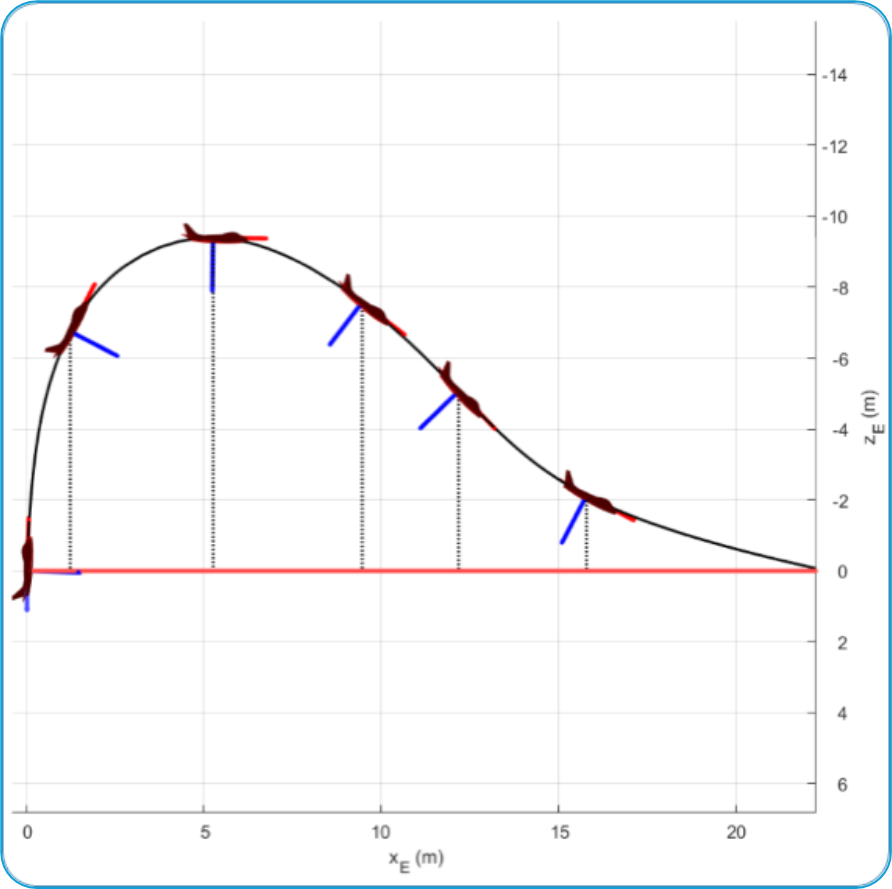

Figure 1 - Desired aircraft flight

### Motivation

ASRW 2023 competition demands teams to develop a low-cost reusable rocket-powered aerospace vehicle which is destabilized by the movement of water stored in an unpressurised tank located on the rear side of the vehicle. The vehicle design shall incorporate mechanisms to manage the dynamic forces introduced by the sloshing water to maximize its range, time of flight, and liquid payload capacity. 

To achive this goal of maximum range, endurance and stable flight, the Airsloths team decided to develop the simulation with MATLAB and Simulink to study the effect of tail contribution and accordingly optimize the vehicle design. This code was developed with the following assumptions: 

- Complete aircraft is a rigid body.

- There is zero sloshing.

- There is zero latency in avionics.

- Aircraft has longitudinal symmetry. 

The main idea was to actively regulate the pitching moment law to alter the trajectory, a concept which led to a non-conventional design for the lifting surfaces, consisting of a foldable V-tail (Figure 2). Hence, the control law translated into an opening-angle change with the elevation angle, to smoothly change the configuration from a "rocket" (tail "closed") into a "glider" (tail "open"). The aircraft must pitch down until it reaches a point after the apogee where the speed is enough to smoothly land through a pull-up maneuver. This tailplane also plays a crucial role in counteracting the destabilizing effects of liquid sloshing, ensuring a controlled descent.

This code contains additional files that can be accessed via the repository (P.S.: link to be added here).

### Aircraft

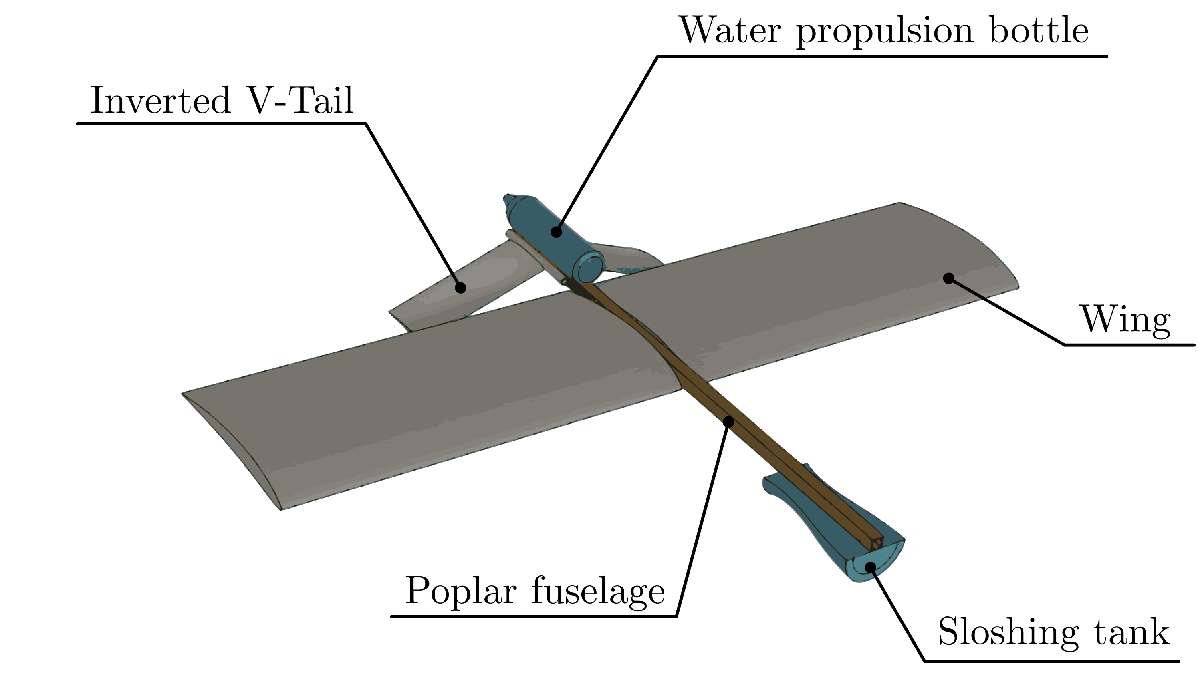

Figure 2 - Aircraft model CAD

The water rocket-glider developed by the AirSloths team was engineered using lightweight and durable materials, mainly polar wood and polystyrene + carbon fiber reinforcement. The propulsion system utilized a 2-liter PET bottle, filled with 0.7 liters of water, pressurized to 10 bars, which provided the necessary thrust for takeoff. The sloshing tank was 3-D printed. The aircraft’s flight computer measures key parameters such as altitude and elevation angle, with the latter being used to adjust the folding angle of the tailplane for precise control throughout the flight mission.

## Aircraft mathematical modeling

### Architecture setup

To start modeling our aircraft, we used [`defineAircraftComponents.mlx`](matlab:open('./defineAircraftComponents.mlx')) to construct a data structure aircraftParts to store the assigned geometric properties of the components. The defineAircraftComponents function was complemented with [`defineMaterialDensities.mlx`](matlab:open('./defineMaterialDensities.mlx')) to define densities of various component materials.

aircraftParts = defineAircraftComponents(defineMaterialDensities);

Now that all aircraft components have been defined, we can create the aircraft model, as aircraftConfiguration data structure, using [`buildAircraft.mlx`](matlab:open('./buildAircraft.mlx')). The algorithm describes the latter as a system of material points.

aircraftConfiguration = buildAircraft(aircraftParts);

### Inertial properties evaluation

Inertial properties of aircraft was calculated using [`setupInertia.mlx`](matlab:open('./setupInertia.mlx')). 

inertialData = setupInertia(aircraftConfiguration);

The tail arm length, distance between the Horizontal Tail (HT) and the aircraft Center of Gravity (CG), was one of the main design optimization object .

aircraftConfiguration.r_G = inertialData.r_G;
aircraftConfiguration.HT.Arm = inertialData.r(7,1) - aircraftConfiguration.r_G(1);

### Aerodynamics modeling

To perform the aerodynamic analysis, a total 8 configurations of the aircraft was prepared with the folding angle variation between 0 to 75 degrees.  Here, 0 degree folding angle converts aircraft to a rocket mode and 75 degree relates to fully opened wings for gliding. 

To obtain aerodynamics coefficients of the aircraft, [Digital Datcom](https://www.pdas.com/datcom.html) was used. This Digital Datcom data was imported with builtin [datcomimport](https://in.mathworks.com/help/releases/R2024b/aerotbx/ug/datcomimport.html?searchPort=53145) function of MATLAB. The imported data is available in the [setupAerodynamics.mlx](matlab:open('./setupAerodynamics.mlx')).  

aerodynamicData = setupAerodynamics();

This imported data is finally modeled in the form of lookup tables in the Simulink model. The aerodynamic coefficients used in the simulation are:

- $C_D$:     Drag coefficient

- $C_L$:     Lift coefficient

- $C_M$:    Pitching moment coefficient

- $C_{M_0}$:   Pitching moment coefficient at zero angle of attack

- $C_{M_q}$:   Pitching moment coefficient derivative with respect to the pitch rate (q). It indicates the change in pitch moment due to the aircraft’s rotation.

- $C_L^{\mathrm{(tail)}}$: Lift coefficient for the tailplane. It is the key of the control law.

### Propulsion modeling

This aircraft is powered by water propulsion. To calculate the thrust profile, first, speed profile of the exhaust flow was computed using the [Water Rocket Simulator](https://waterrocketsimulator.github.io/). This speed profile was  discretized and fed to a function called [`massflowRate.mlx`](matlab:open('./massflowRate.mlx')) to compute the mass evolution. The mass evolution was calculated by integrating the mass flow $\dot{m}=\rho VA$ over time, where $\rho$, $V$, and $A$ are the water density,  speed of the water at the nozzle, and  section area of the nozzle respectively. This mass evolution data was used to calculate the thrust profile. 

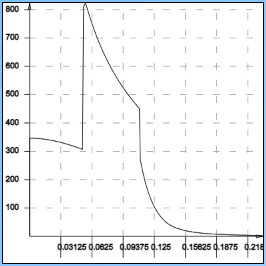

Figure 3 - Thrust Profile

Finally, the thrust profile along with eccentricity was modeled with setupPropulsion  [`setupPropulsion.mlx`](matlab:open('./setupPropulsion.mlx'))`. `The eccentricity is important to calculate the pitching moment due to the thrust itself.

propulsionData = setupPropulsion(aircraftConfiguration);

## Flight simulation

To evaluate the gliding performance of the aircraft, a Simulink model, [`simulateFlight.slx`](matlab:open('./simulateFlight.slx')), was developed. It models, simulates, and compares the performance of two different configurations to study the effect of aircraft tail:

- **Glider Configuration**: models the aircraft dynamics with the tail deployment. Along with the trajectory, it also returns the aircraft attitude $$\theta$$ to represent the aircraft orientation as well. 

- **Non-Gliding Configuration:** models the aircraft dynamics like glider configuration except the tail contribution.

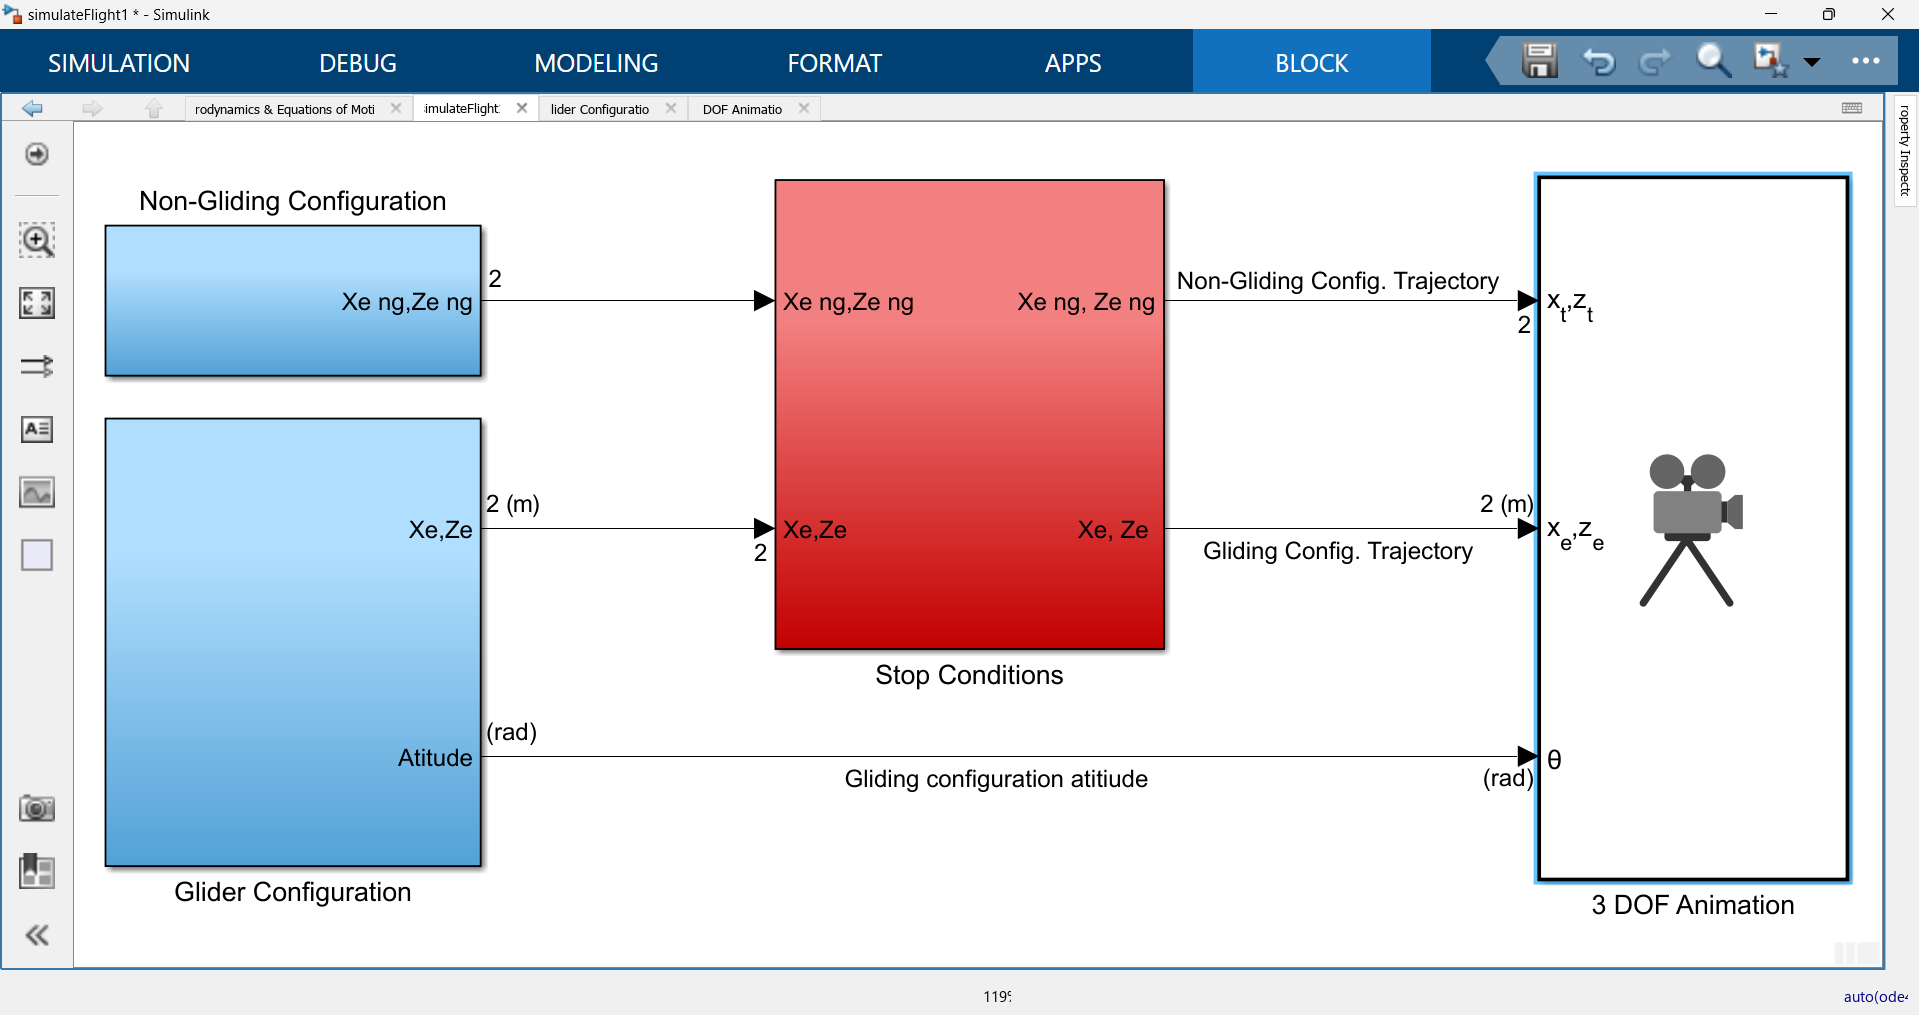

Figure 4 - Simulink model

Along with the aircraft dynamics modeling of both configurations, stop conditions were also modeled to make sure that the aircraft did not attain a negative altitude. Finally, for the visualization DOF animation block was used.

#### Aircraft dynamics modeling

For both, Gliding and Non-Gliding configurations, aircraft dynamics were modeled with the following key sub-systems:

- Forces and Moments: To model forces and moments, [Aerodynamic data](about:blank<#H_15e2%3E) and [Propulsion data](about:blank<#H_2781%3E) were imported to Simulink through lookup tables. This data was complemented with various flight data parameters to calculate Forces and Moments. It also has a pitching moment filter to take into account the first 0.064s of the flight when the aircraft is still getting out of the launch tube, designed to absorb the aggressive pitch impulse and provide the aircraft appropriate directions.

- Equations of motion: To model equation of motion with variable mass and inertia, the [Custom Variable Mass 3DOF (Wind Axes)  ](https://in.mathworks.com/help/releases/R2024b/aeroblks/customvariablemass3dofwindaxes.html?searchPort=61930)block was used. It was supplemented by the variable [mass data ](matlab:open('./massflowRate.mlx'))and inertia data, essential for simulating dynamic changes in the vehicle’s mass and inertia during flight or movement. This block also models the gravitational forces. This subsystem provides the effect of the forces and moments on the aircraft in terms of various aircraft states.

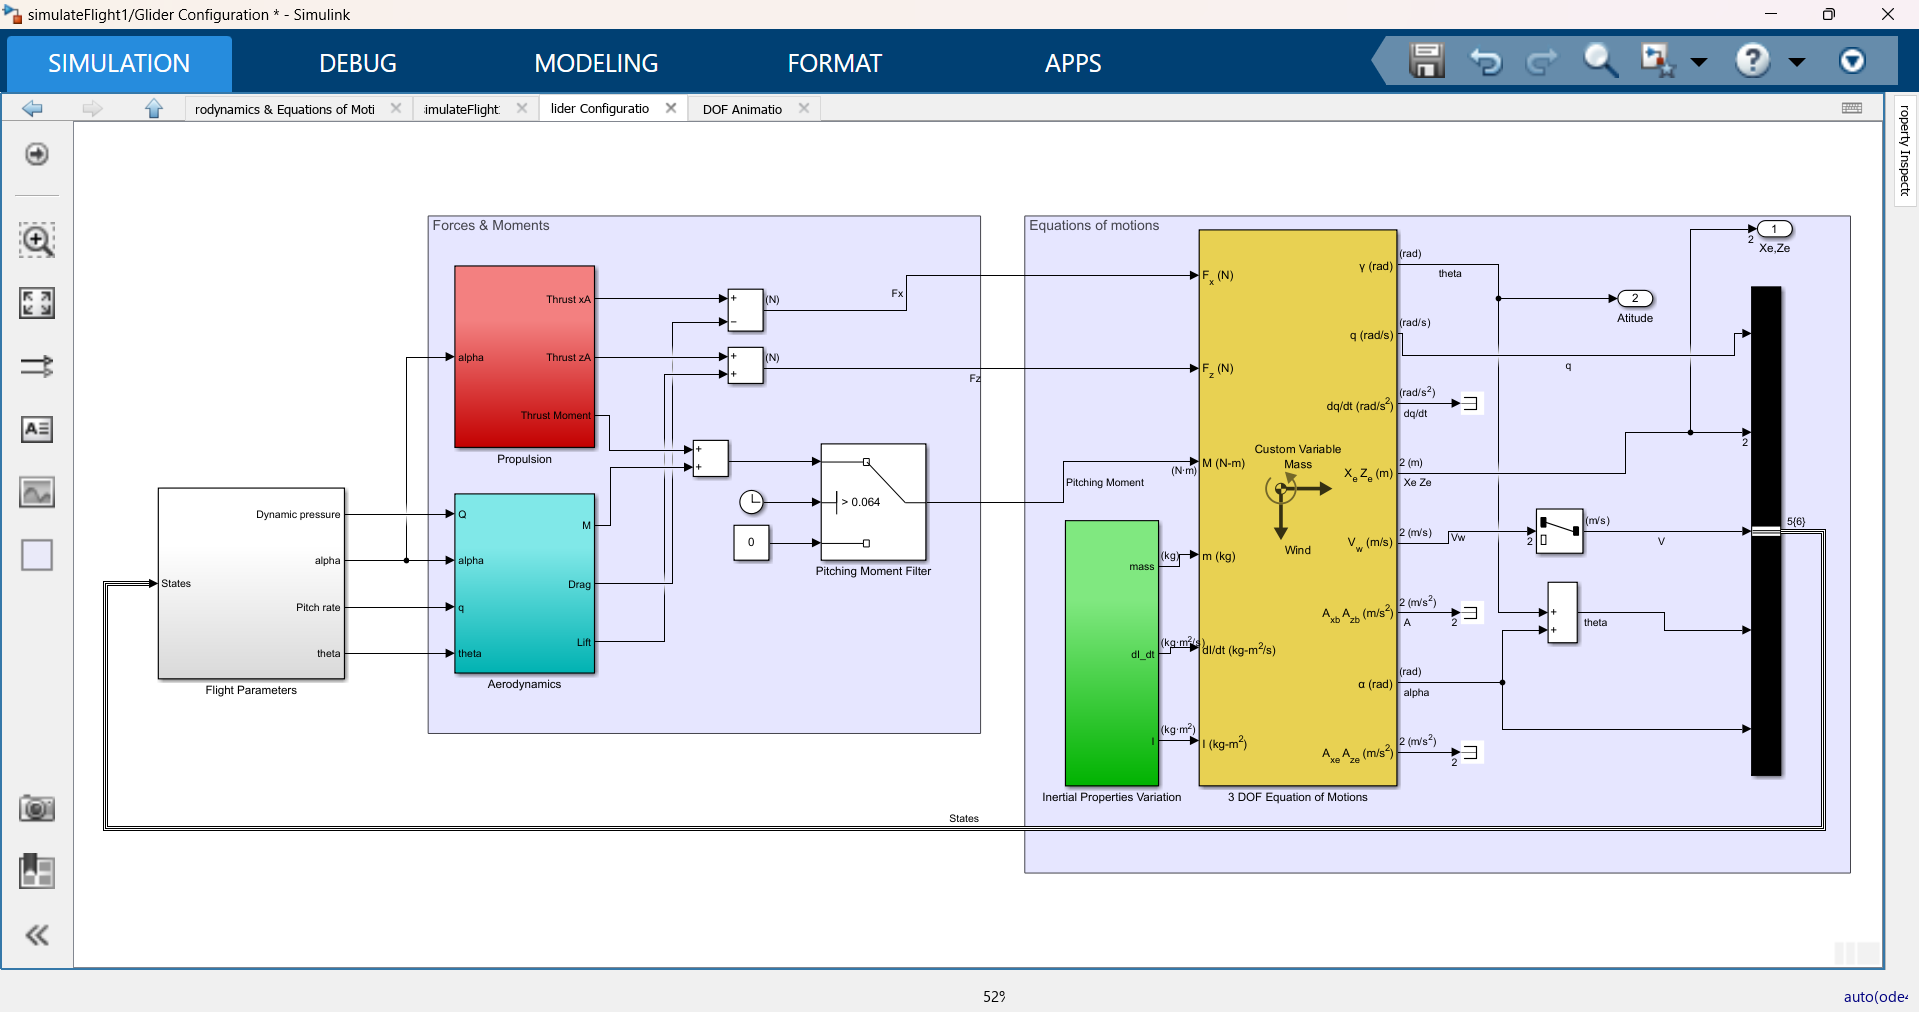

Figure 5 - Aircraft dynamics modeled in both configuration

#### Initial conditions

The competition requirements governed the initial condition of the vehicles. For the ASRW competition 2023, the rocket had to be launched at  an elevation angle of 88 degrees. All other parameters were considered zero except initial speed to simplify the numerical complexities.

xE0 = 0; yE0 = 0; zE0 = 0;                                      % Position
theta0 = convang(88,'deg','rad');                               % Launch elevation angle
q0 = 0;                                                         % Pitching speed
alpha0 = 0;                                                     % Angle of attack
V0 = 0.1;                                                       % Linear speed (almost 0, numerical reasons)

#### Simulation results

results = sim("simulateFlight.slx");
nonglidingRange =  max(results.Trajectory.Data(:,1));           % range of non-gliding configuration
glidingRange    =  max(results.Trajectory.Data(:,3));           % range of gliding configuration

rangeBenefit = 6.5458

rangeBenefit = glidingRange - nonglidingRange                   % range benefit

maxAltitude = 8.4987

maxAltitude = max(-results.Trajectory.Data(:,4))

Simulation results show  that the gliding configuration with the tail activated provided a range advantage of 6.545 m compared to the non-gliding mode configuration. Also, both configurations achieved a maximum altitude of 8.4987 meters.

## Conclusions

The simulation shows that the glider gains range through a pull-up maneuver, aided by the tailplane design, ensuring stable flight without stalling. The goal of achieving instability at the apex, leading to a rapid pitch-down for gaining airspeed, was successfully met. Also, this airspeed generates necessary lift from the wings and tailplane for a smooth landing. Thrust eccentricity also proved effective, enhancing range by 6.54 meters and controlling the elevation angle at the apex. Although, the simulation results were approximate but close to flight test results ([AirSloths Flight Tests Video](https://www.youtube.com/watch?v=y8TNEQP7Qss)). These simulated results were used Iteratively to test and improve the overall design.